# PRÁCTICA 3

Ecuación 1 práctica y ecuación 3 apuntes

# Calibración de cámaras en Matlab (Camera Calibrator App)

MatLab dispone de una aplicación para la calibración de cámaras (Camera Calibrator App) que le permite estimar los parámetros intrínsecos y extrínsecos de la cámara, así como los coeficientes de distorsión de la lente empleada. Estos parámetros se pueden emplear en varias aplicaciones de visión por computador como son: eliminar distorsiones en las imágenes, medir objetos sobre un plano y reconstruir escenas tridimensionales mediante el uso de varias cámaras.

## CALIBRACIÓN DE UNA SOLA CÁMARA

Para calibrar la cámara hay que seguir el siguiente diagrama de flujo usando la aplicación.

- Preparar imágenes: Preparar las imágenes y/o la cámara, y el panel de calibración. (damero)

- Añadir imágnes: Cargar/Capturar las imágenes

- Calibración: Calibrar la cámara

- Evaluación: Evaluar la precisión de la calibración

- Mejora: Ajustar los parámetros para mejorar la precisión (si fuese necesario)

- Exportar resultados: Exportar el resultado de la calibración

### cameraCalibrator

En esta práctica se va a emplear esta herramienta para calibrar dos cámaras, una Intel RealSense 435 RGB y una GoPro que monta un gran angular que deforma la imagen de manera considerable. Para ello se utilizarán imágenes contenidas en los subdirectorios ‘RealSense’ y ‘GoPro’ las que muestran un panel de calibración tipo damero con casillas de 30x30 mm y 50x50 mm respectivamente.

## CARGAR IMÁGENES

### EJERCICIOS

1. Cargue las imágenes ‘realsense01.png’ a ‘realsense20.png’ (20 imágenes en total). Dichas imágenes están contenidas en el subdirectorio ..\Practica03\RealSense. Especifique un tamaño de celda de 30x30.

cameraCalibrator

2. Visualice las imágenes descartadas por el sistema de calibración

- realsese20.pic: rechazada porque tiene una libreta sobre el tablero

3. Compruebe visualmente que se han detectado correctamente los puntos de cruce del panel en las imágenes de calibración aceptadas

- El origen se dibuja en color naranja

## CALIBRAR

El algoritmo de calibración emplea inicialmente un modelo pin hole sin distorsión, estimando una matriz de parámetros intrínsecos únicos para la cámara y una matriz de rotación y vector de translación para cada una de las imágenes. Posteriormente calcula los coeficientes de distorsión mediante minimización no lineal de mínimos cuadrados:

- Coordenadas en el mundo de un conjunto de puntos: XYZ1 = [-30 -30 0 1; -30 150 0 1; 240 150 0 1;240 -30 0 1]; % bordes del tablero en plano de la imagen

- Matriz de rotación de la imagen 3: R3 = parametrosRealSense.RotationMatrices(:,:,3);

- Vector de traslación de la imagen 3: t3 = parametrosRealSense.TranslationVectors(3,:);

- Parámetros intrínsecos de la cámara: K = parametrosRealSense.IntrinsicMatrix;  % parametrosRealSense.K

- Modelo de la cámara para imagen 3: M3 =  [R3 ; t3] * K ; % paso de coordenades del mundo real a pixeles de la cámara

- Coordenadas homogéneas de proyección de un conjunto de puntos en la imagen: wxy1 = XYZ1 * M3; % w[x y 1] con w variable arbitraria para coordenadas homogéneas

- Coordenadas  en pixeles de proyección de un conjunto de puntos en la imaen: xy1 = wxy1 ./ wxy1(:,3) % [x y 1]

- Recogida de posición en el la imagen: puntos2d = ginput();

- Paso de coordenadas de la imagen (pixeles) a coordenadas en el mundo real: puntos3D = pointsToWorld(parametrosGoPro, R, t, puntos2d);

### EJERCICIO

4. Realice la calibración con las imágenes suministradas con el objetivo de obtener una matriz de parámetros intrínsecos, 2 coeficientes de distorsión radial y una matriz de rotación y un vector de traslación para cada imagen (posiciones de la cámara).

## EVALUAR EL RESULTADO DE LA CALIBRACIÓN.

- Sobre cada imagen se representan tanto los puntos detectados como los proyectados empleando con el modelo del cámara obtenido durante la calibración (1)

- Muestra el error medio en píxeles para cada imagen (2)

- Representa los parámetros extrínsecos en el espacio 3D (3)

- Permite corregir la distorsión de la imagen (4)

### EJERCICIO

5. Analice los resultados obtenidos. ¿En qué posición se producen mayores errores?

- Cuando el tablero no es perpendicular a la cámara

## EXPORTAR EL RESULTADO DE LA CALIBRACIÓN

Una vez completada la calibración es posible exportar los parámetros como un objeto del tipo cameraParameters o bien mediante un MATLAB script. Este script permite repetir la calibración completa y mostrar el resultado de la misma.

### EJERCICIO

6. Exporte el resultado de la calibración sobre una variable llamada parametrosRealSense.

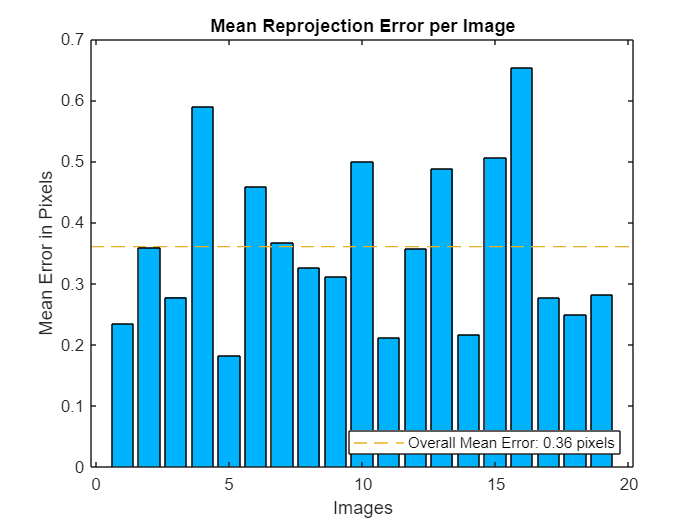

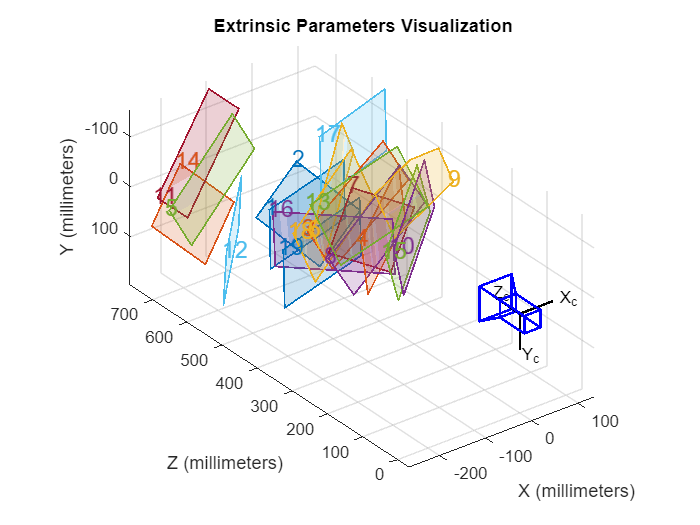


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  600.9523 +/- 2.1289      598.5395 +/- 2.1342  ]
Principal point (pixels):[  323.3885 +/- 1.3901      240.5781 +/- 0.7221  ]
Radial distortion:       [    0.0664 +/- 0.0071       -0.1126 +/- 0.0278  ]

Extrinsics
----------
Rotation vectors:
                         [    0.0060 +/- 0.0059       -0.2541 +/- 0.0045       -0.0256 +/- 0.0008  ]
                         [    0.0242 +/- 0.0053       -0.0258 +/- 0.0045        0.8111 +/- 0.0007  ]
                         [    0.0422 +/- 0.0048       -0.0952 +/- 0.0034       -0.5448 +/- 0.0005  ]
                         [    0.0064 +/- 0.0019       -0.5894 +/- 0.0023       -0.1838 +/- 0.0006  ]
                         [    0.0921 +/- 0.0115       -0.2461 +/- 0.0086       -0.5702 +/- 0.0015  ]
                         [    0.2037 +/- 0.0025       -0.5929 +/- 0.0028       -0.6108 +/- 0.0007  ]
 

scrptParametrosRealSense();

parametrosRealSense = cameraParams; % cameraParameters

Una variable de tipo cameraParameters contiene un total de 18 campos que reflejan el resultado de la calibración.

parametrosRealSense 

Unrecognized function or variable 'parametrosRealSense'.

#### EJERCICIOS

7. Almacene y muestre la matriz de parámetros intrínsecos en la variable K (es única para la cámara)

K = parametrosRealSense.K % no vale para la fórmula porque es la traspuesta de la que necesitamos

K =   600.9523         0  323.3885
         0  598.5395  240.5781
         0         0    1.0000


K = parametrosRealSense.IntrinsicMatrix % esta es la que usamos, cx=323.4 (640/2), cy=240.6 (480/2)

K =   600.9523         0         0
         0  598.5395         0
  323.3885  240.5781    1.0000


¿Se corresponde la coordenada del punto principal con el centro del sensor?

- Aproximadamente. Se desvía 3 pixeles en el eje x

8. Almacene y muestre la matriz de rotación y el vector de translación para la cámara en la posición 3 (variables R y t respectivamente)

- Nota: Los índices en la variable de calibración para cada posición se corresponde con el número que la aplicación le ha asignado a la imagen correspondiente y no al nombre del fichero que contiene la imagen.

numImagen = 3;
R3= parametrosRealSense.RotationMatrices(:,:,numImagen)

R3 =     0.8510   -0.5192    0.0792
    0.5153    0.8545    0.0654
   -0.1016   -0.0148    0.9947


t3 = parametrosRealSense.TranslationVectors(numImagen,:)

t3 =  -138.2220  -19.4032  427.0059


9. Según la ecuación 1, obtenga la matriz una matriz M de 4x3 que modele la cámara ubicada en la posición 3. 

M3 =  [R3 ; t3] * K % paso de coordenades del mundo real a pixeles de la cámara

M3 = 1.0e+04 *

    0.0537   -0.0292    0.0000
    0.0331    0.0527    0.0000
    0.0261    0.0230    0.0001
    5.5024    9.1115    0.0427


Emplee dicha matriz para calcular donde se proyectan los puntos de 3D de coordenadas (-30, -30, 0), (-30, 150,0), (240,150,0) y (240,-30,0), los cuales representan los puntos extremos de la rejilla expresados en milímetros, los puntos debe guardarlos en una variable llamada ‘puntos’, cada punto en una fila (4x3).

% p = [-30 -30 0 1; -30 150 0 1; 240 150 0 1;240 -30 0 1]; % coordenada aumentadas
XYZ1 = [-40 -40 0 1; -30 150 0 1; 240 150 0 1;240 -30 0 1] %240 -30 0 1] % bordes del tablero en plano de la imagen

XYZ1 =    -40   -40     0     1
   -30   150     0     1
   240   150     0     1
   240   -30     0     1


wxy1 = XYZ1 * M3 % w[x y 1] con w variable arbitraria para coordenadas homogéneas

wxy1 = 1.0e+05 *

    0.2031    0.8170    0.0042
    0.8854    1.7894    0.0043
    2.3352    1.0018    0.0046
    1.7398    0.0528    0.0044


NOTA: tenga en cuenta que se las coordenadas en el plano imagen se obtienen inicialmente en su forma homogénea.xy1 = wxy1 ./ wxy1(:,3) % [x y 1]

10 Superponga los puntos obtenidos anteriormente sobre la imagen correspondiente empleando función de Matlab fill (rellena la región determinada por un conjunto de puntos).

figure;
im3 = imread("./Realsense/realsense03.png");
imshow(im3);
hold on
fill (xy1(:,1), xy1(:,2), 'r' ,'FaceAlpha', 0.5);
axis on

puntos2d = ginput(1)


11. Una vez completada la práctica repita los ejercicios del 7 al 10 con otras imágenes

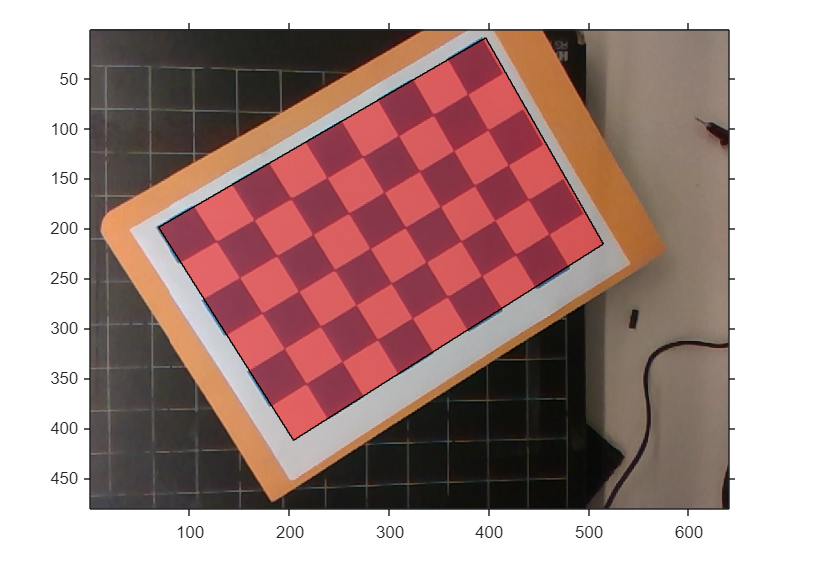

numImagen = 16;
R = parametrosRealSense.RotationMatrices(:,:,numImagen)

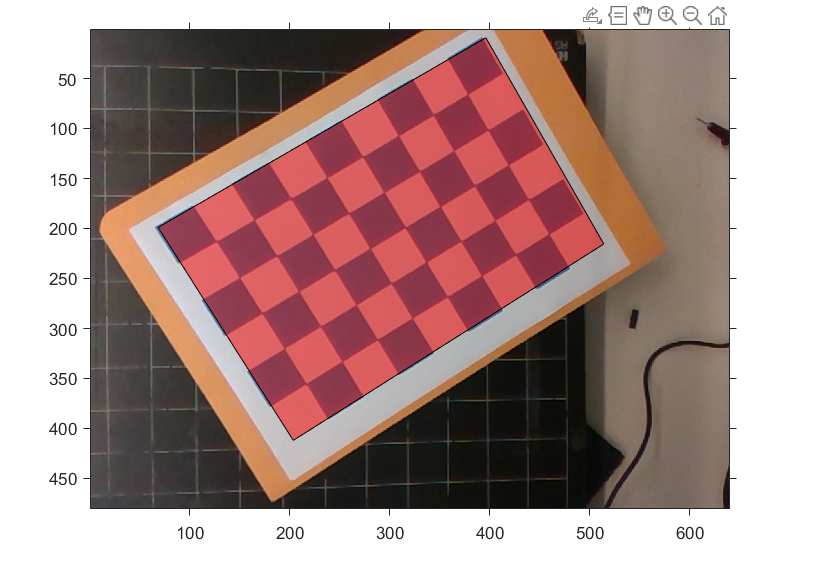

puntos2d =    70.0000  198.0000


t = parametrosRealSense.TranslationVectors(numImagen,:)
M =  [R ; t] * K % paso de coordenades del mundo real a pixeles de la cámara

wxy1 = XYZ1 * M % w[x y 1] con w variable arbitraria para coordenadas homogéneas
xy1 = wxy1 ./ wxy1(:,3) % [x y 1]
im = imread(sprintf("./Realsense/realsense%02d.png", numImagen));
imshow(im);
hold on;

R =     0.6928   -0.0146   -0.7210
    0.1059    0.9910    0.0817
    0.7133   -0.1329    0.6881


fill (xy1(:,1), xy1(:,2), 'r' ,'FaceAlpha', 0.5);

t =  -166.6579  -39.8493  487.4784


axis on;

M = 1.0e+04 *

    0.0183   -0.0182   -0.0001
    0.0090    0.0613    0.0000
    0.0651    0.0086    0.0001
    5.7491    9.3425    0.0487


grid on;

wxy1 = 1.0e+05 *

    0.4929    0.8051    0.0051
    0.6550    1.9081    0.0052
    1.1496    1.4162    0.0033
    0.9875    0.3131    0.0031


## CORRECCIÓN DE IMÁGENES

Una vez realizada la calibración de la cámara es posible emplear el resultado obtenido para corregir las distorsiones producidas por la lente y posibles errores de montaje.

### Ejercicios

12. Realice la calibración de una cámara GoPro con gran angular a partir de las imágenes contenidas en el subdirectorio ‘..\Practica03\GoPro’. 

scriptParametrosGoPro();

xy1 =    97.2940  158.8977    1.0000
  125.6418  365.9909    1.0000
  351.8917  433.4969    1.0000
  316.5178  100.3663    1.0000


Exporte el resultado sobre la variable parametrosGoPro y muestre los coeficientes de distorsión radial obtenidos.

parametrosGoPro = cameraParams;
parametrosGoPro.RadialDistortion

13. Emplee el botón ‘show undistorted’ de la propia aplicación de calibración para mostrar cada imagen corregida.

- ´Ver sesión de calibración

14. Muestre sobre una figura las imágenes ‘gopro01.jpg’ y ‘gopro05.jpg’ con distorsión y el resultado de corregirlas. (subplot(2,2,..))

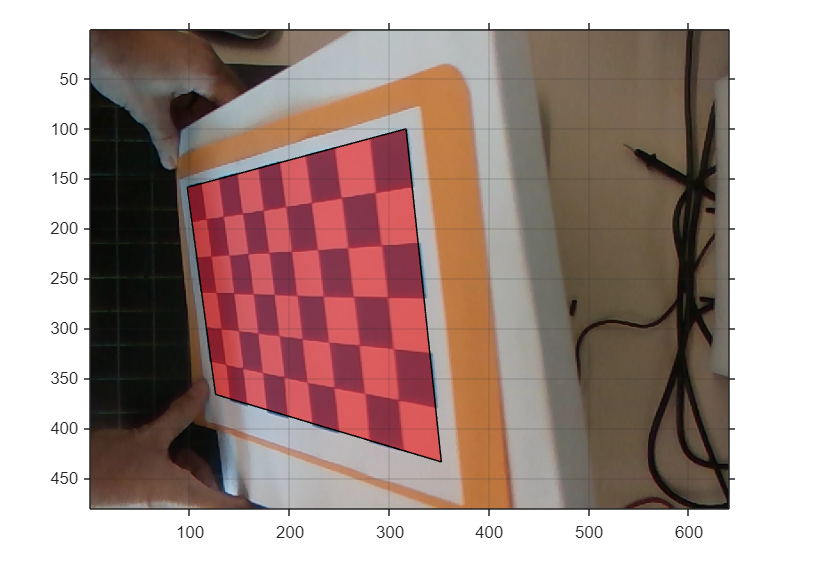

numImagen = 1;
figure;
subplot(2,2,1);
imd = imread(sprintf("./GoPro/gopro%02d.jpg", numImagen));

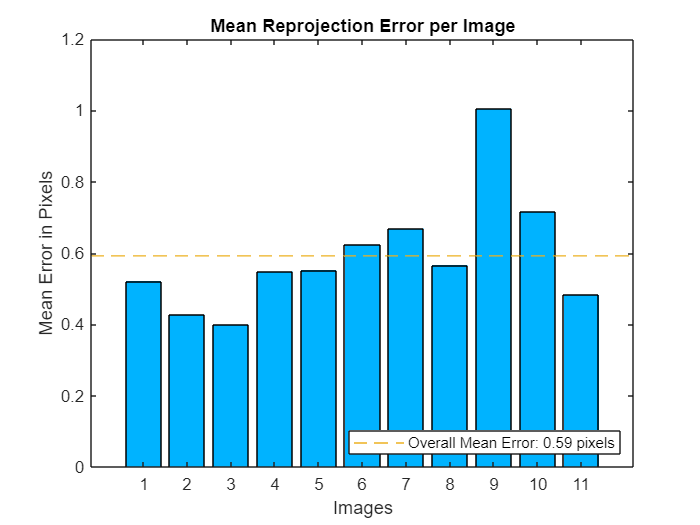

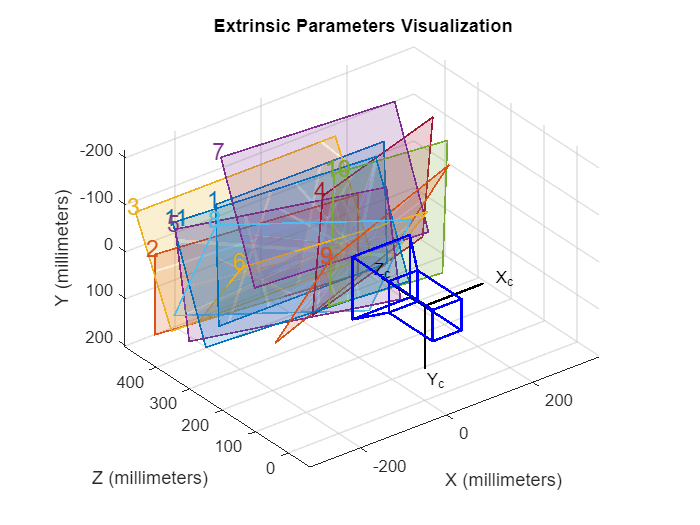


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [  873.2617 +/- 0.9329      872.4386 +/- 0.9150  ]
Principal point (pixels):[ 1006.5832 +/- 0.7118      743.3432 +/- 0.5749  ]
Radial distortion:       [   -0.2549 +/- 0.0012        0.0689 +/- 0.0011  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.0693 +/- 0.0011       -0.0274 +/- 0.0009        0.0258 +/- 0.0002  ]
                         [    0.3624 +/- 0.0010        0.2953 +/- 0.0010       -0.1965 +/- 0.0003  ]
                         [   -0.2154 +/- 0.0010        0.3446 +/- 0.0010       -0.1941 +/- 0.0003  ]
                         [    0.0283 +/- 0.0009       -0.3797 +/- 0.0010        0.0829 +/- 0.0003  ]
                         [    0.0147 +/- 0.0008        0.4574 +/- 0.0009       -0.1214 +/- 0.0003  ]
                         [    0.6770 +/- 0.0009        0.1083 +/- 0.0009       -0.0383 +/- 0.0004  ]
 

imshow(imd);

subplot(2, 2, 2);
imu = undistortImage(imd, parametrosGoPro);
imshow(imu);

numImagen = 5;

subplot(2,2,3);
imd = imread(sprintf("./GoPro/gopro%02d.jpg", numImagen));
imshow(imd);


ans =    -0.2549    0.0689


subplot(2, 2, 4);
imu = undistortImage(imd, parametrosGoPro);
imshow(imu);

## OBTENER COORDENADAS 3D A PARTIR DE IMÁGENES

La calibración también permite emplear una función para calcular las coordenadas X, Y de un punto en el espacio 3D asociado a un determinado plano de calibración (Z = 0), esta función es:

NOTA: los puntos 2D de la imagen deben ser sin distorsión.

### EJERCICIO

15. Realice un script que permita marcar dos puntos sobre la imagen ‘realsense20.png’ (ginput), y superponga sobre la imagen la línea que los une y la distancia real que los separa (en centímetros) (comando text). Para ello deberá emplear la variable obtenida durante la calibración de la misma en el ejercicio 6, y tener en cuenta que los objetos se encuentran sobre el plano de la rejilla en la posición que se muestra en la imagen ‘realsense03.png’.

% ESTO ES DE LA IMAGEN 3
figure;
subplot(1,2,1);
imshow(imread(sprintf("./Realsense/realsense%02d.png", 20)));
subplot(1,2,2);
imshow(imread(sprintf("./Realsense/realsense%02d.png", 3)));

K = parametrosRealSense.IntrinsicMatrix % esta es la que usamos, cx=323.4 (640/2), cy=240.6 (480/2)
numImagen = 3;
R= parametrosRealSense.RotationMatrices(:,:,numImagen)
t = parametrosRealSense.TranslationVectors(numImagen,:)
M =  [R ; t] * K % paso de coordenades del mundo real a pixeles de la cámara

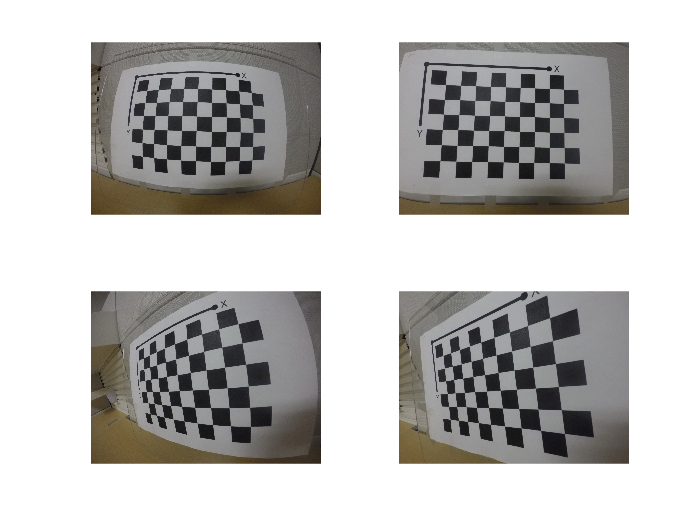

figure;
subplot(1,1,1);
imshow(imread(sprintf("./Realsense/realsense%02d.png", 20)));
hold on;
axis on;
grid on;
puntos2d = ginput(2);

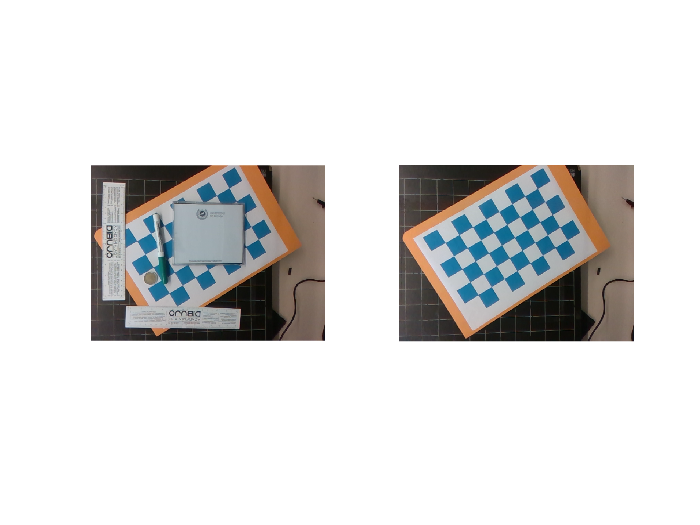

% la variable’ distan’ contiene la distancia calculada
% x e y puede ser el valor medio de los puntos marcados.
puntos3d = pointsToWorld(parametrosRealSense, R, t, puntos2d);
dist = norm(puntos3d(1,:)-puntos3d(2,:));

plot(puntos2d(:, 1), puntos2d(:,2), 'y');

etiqueta = sprintf("P1=(%0.0f,%0.0f)->(%0.0f,%0.0f)", puntos2d(1,1), puntos2d(1,2),puntos3d(1,1), puntos3d(1,2));
text (puntos2d(1,1),puntos2d(1,2),etiqueta,'Color','y');

etiqueta = sprintf("P2=(%0.0f,%0.0f)->(%0.0f,%0.0f)", puntos2d(2,1), puntos2d(2,2),puntos3d(2,1), puntos3d(2,2));
text (puntos2d(2,1),puntos2d(2,2),etiqueta,'Color','y');

etiqueta = sprintf("Distancia = %0.1f", dist);

text (mean(puntos2d(:,1)),mean(puntos2d(:,2)),etiqueta,'Color','y');

puntos2d

K =   600.9523         0         0
         0  598.5395         0
  323.3885  240.5781    1.0000


puntos3d
dist

R =     0.8510   -0.5192    0.0792
    0.5153    0.8545    0.0654
   -0.1016   -0.0148    0.9947


sqrt((puntos3d(1,1)-puntos3d(2,1))^2+(puntos3d(1,2)-puntos3d(2,2))^2)

t =  -138.2220  -19.4032  427.0059


norm(puntos3d)

M = 1.0e+04 *

    0.0537   -0.0292    0.0000
    0.0331    0.0527    0.0000
    0.0261    0.0230    0.0001
    5.5024    9.1115    0.0427


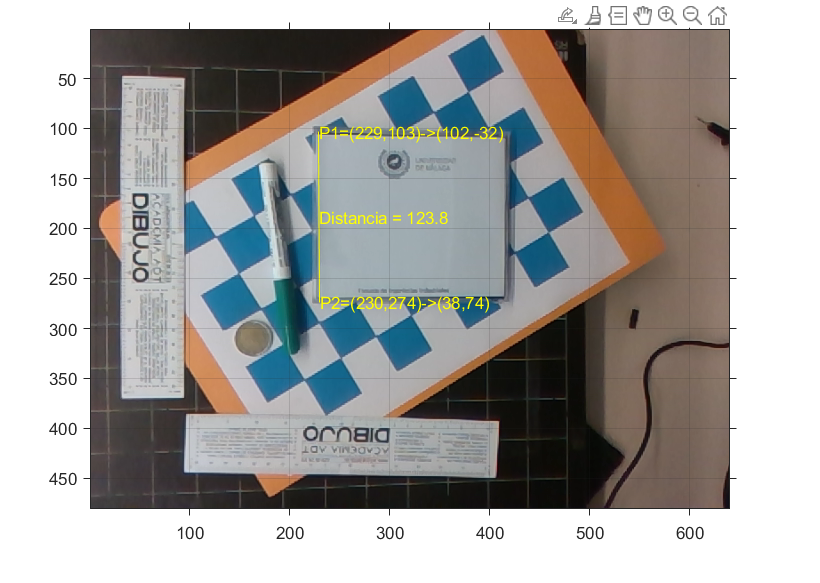

puntos2d =   226.0000  102.0000
  226.0000  271.0000


puntos3d =   100.3466  -33.5738
   36.7505   70.8843


dist = 107.3713

ans = 122.2946

ans = 107.3713

ans = 107.3713

 norm - Vector and matrix norms
    This MATLAB function returns the Euclidean norm of vector v.

    Syntax
      n = norm(v)
      n = norm(v,p)

      n = norm(X)
      n = norm(X,p)
      n = norm(X,"fro")

    Input Arguments
      v - Input vector
        vector
      X - Input array
        matrix | array
      p - Norm type
        2 (default) | positive real scalar | Inf | -Inf

    Output Arguments
      n - Norm value
        scalar

    Examples
      Vector Magnitude

norm(puntos3d')
help norm

NOTA: La caratula trasera de un CD mide 14x12 cm, un rotulador 14 cm, una moneda de 2 euros 2.5 cm de diámetro y cada celda de la rejilla es de 3x3 cm.